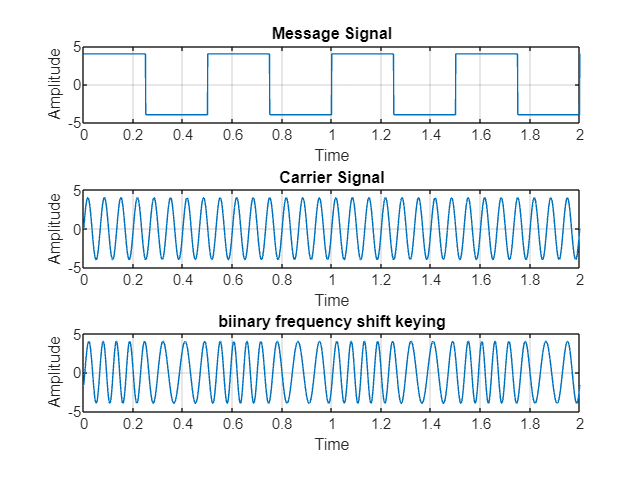

clc;
close all;
am = 4;
ac = 4;
t = 0:0.001:2;
fc = 15;
fm = 2;
kf = 1;

m = am * square(2 * pi * fm * t);
subplot(3, 1, 1);
plot(t, m);
grid on;
title('Message Signal');
xlabel('Time');
ylabel('Amplitude');

c = ac * sin(2 * pi * fc * t);
subplot(3, 1, 2);
plot(t, c);
grid on;
xlabel('Time');
ylabel('Amplitude');
title('Carrier Signal');

beta = (kf * am) / fm;
st = ac * cos(2 * pi * fc * t - beta * cos(2 * pi * fm * t));
subplot(3, 1, 3);
plot(t, st);
grid on;
xlabel('Time');
ylabel('Amplitude');
title('biinary frequency shift keying');